## Image Scores

%%% STANFORD IMAGES %%%
% 1 -  (1/1)
% 2 -  (2/2)
% 3 -  (3/3)
% 4 -  (1/1) 
% 5 -  (2/3) Marker Detection
% 6 -  (1/1) 
% 7 -  (2/2)
% 8 -  (1/1)
% 9 -  (3/3)
% 10 - (1/3) Marker Thresholding
% 11 - (1/1)
% 12 - (2/2)
%%% 20/23 Sucessfully Read

%%% JOSEPH IMAGES %%%
% 13 - (1/1) - "Im Joseph! "
% 14 - (2/2) - "ELEX7815 ", "is great"
% 15 - (0/1) - Guide Bar Detection
% 16 - (1/1) - "Test Text. "
% 17 - (1/3) - "aBcDeFgHiJ ", Marker Detection, Weird QR
% 18 - (0/1) - Guide Bar Detction
%%% 5/9 Sucessfully Read

%%% RYAN IMAGES %%%
% 6 -  (3/3) - " Where did ", "you get" , "this code!"
% 8 -  (2/2) - "you get", "this code!"
% 9 -  (1/1) - " Where did "
% 12 - (2/2) - " Where did ", "you get"
%%% 8/8 Sucessfully Read

%%% OVERALL SCORE - 33/40 - 26-11-2019 %%%

## Sample Output

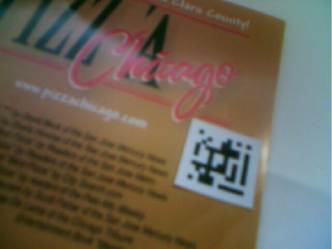 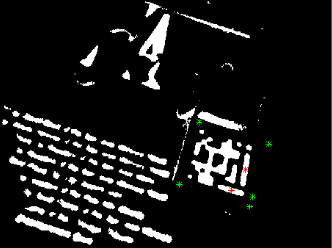

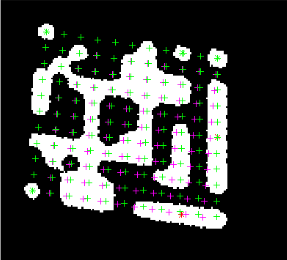 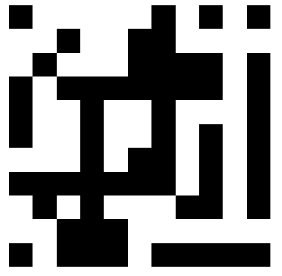

## STANFORD 2D CODE READER - https://web.stanford.edu/class/ee368/Project_06/project.html

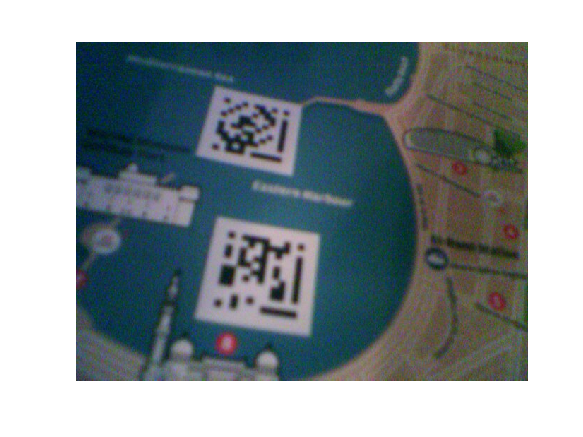

clear;

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%
%          CONSTANTS         %
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%
code = [ ...
    1 0 2 2 2 2 2 2 2 0 1; ...
    0 0 2 2 2 2 2 2 2 0 0; ...
    2 2 2 2 2 2 2 2 2 0 1; ...
    2 2 2 2 2 2 2 2 2 0 1; ...
    2 2 2 2 2 2 2 2 2 0 1; ...
    2 2 2 2 2 2 2 2 2 0 1; ...
    2 2 2 2 2 2 2 2 2 0 1; ...
    2 2 2 2 2 2 2 2 2 0 1; ...
    2 2 2 2 2 2 2 2 2 0 1; ...
    0 0 2 2 2 0 0 0 0 0 0; ...
    1 0 2 2 2 0 1 1 1 1 1];

QR_LENGTH = 11;
QR_WIDTH = 11;
V_BAR_LENGTH = 7;
H_BAR_LENGTH = 5;
CENTER_WEIGHT = 4;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% Choose Image
img = imread('training_12.jpg');
imshow(img);

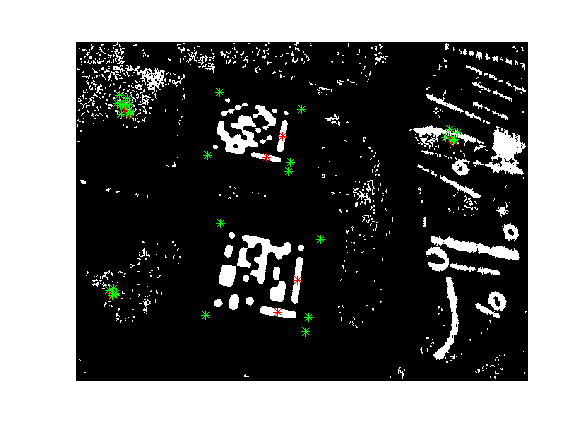

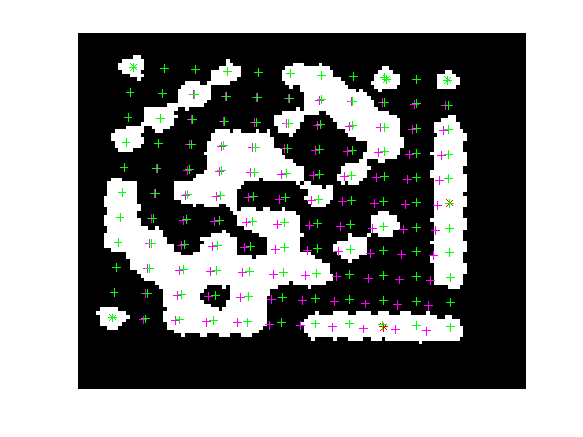

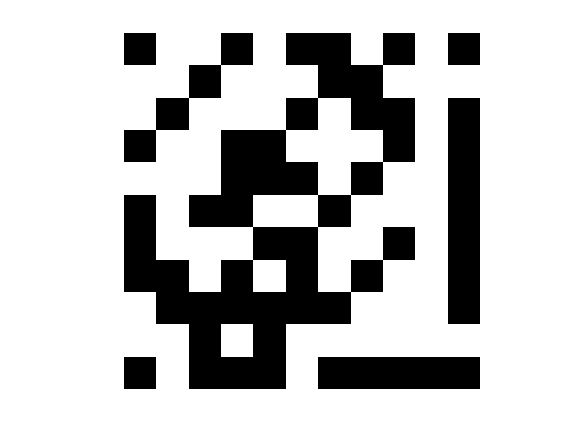

message =     ']
     ÎÑ¯WÄ´¬'


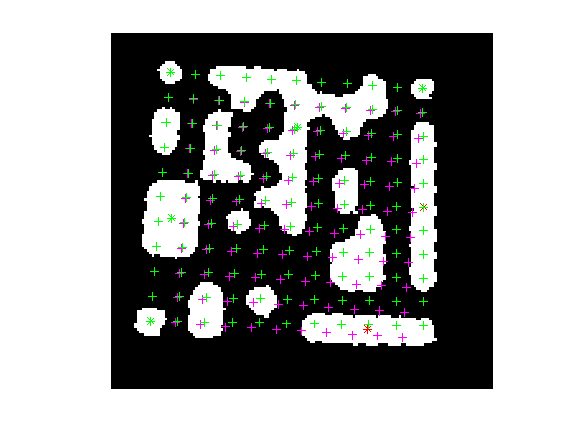

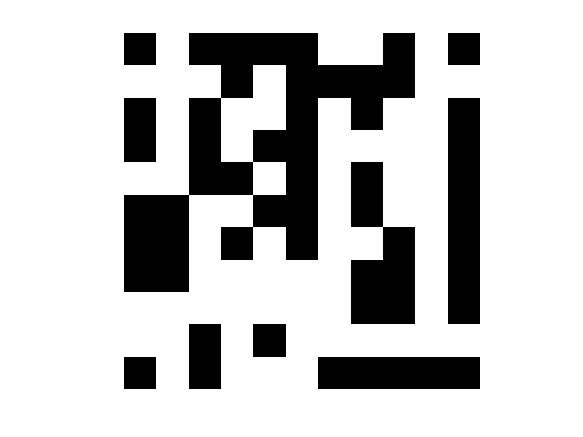

message = 'Ü:áå	Eü@6ðà'


% Threshold
imBinary = imcomplement(imbinarize(rgb2gray(img),'adaptive','ForegroundPolarity','dark'));
imBinary = bwareafilt(imBinary, [4 round(0.02*size(img,1)*size(img,2))]);
imBinary = imclearborder(imBinary);
imshow(imBinary);

% Region Props on thresholded image
stats = regionprops('table', imBinary, 'Centroid', 'MajoraxisLength', 'MinoraxisLength', ...
                    'Orientation', 'Area', 'Solidity');
centroids = cat(1,stats.Centroid);

% Find Guide bar pairs - findGuideBars.m
guideBarPairs = findGuideBars(stats);

% If Guide bars were found, process them
if (~isempty(guideBarPairs))
    
    % Cut Out QR Code from img
    potentialQR = {};
    hold on
    for i = 1:length(guideBarPairs)  
        
        % Plot Guide Bars
        plot(guideBarPairs(i).vBar.Centroid(1), guideBarPairs(i).vBar.Centroid(2), 'r*');
        plot(guideBarPairs(i).hBar.Centroid(1), guideBarPairs(i).hBar.Centroid(2), 'r*');
        
        % Find angle to rotate QR code
        thetaV = guideBarPairs(i).vBar.Orientation;
        thetaH = guideBarPairs(i).hBar.Orientation;
        thetaRot = (90 - wrapTo360(guideBarPairs(i).vBar.Orientation));  % Could be improved to handle upside down case
        dHV = pdist2(guideBarPairs(i).hBar.Centroid, guideBarPairs(i).vBar.Centroid);
        [dHx, dHy] = pol2cart(deg2rad(thetaH), 1);
        
        % If moving along the hBar vector does not get us closer to the
        % vBar, flip the hBar angle.
        if (pdist2(guideBarPairs(i).hBar.Centroid + [dHx, -1*dHy], guideBarPairs(i).vBar.Centroid) > dHV)
            thetaH = thetaH + 180;
        end
               
        hBar_Length = guideBarPairs(i).hBar.MajorAxisLength;
        vBar_Length = guideBarPairs(i).vBar.MajorAxisLength;
        
        QRLength_H = (QR_LENGTH/H_BAR_LENGTH)*hBar_Length;
        QRLength_V = (QR_LENGTH/V_BAR_LENGTH)*vBar_Length;
        
        % Calculate points that will define the QR Code boundary
        vectors = struct('rho', {}, 'theta', {});
        vectors(1) = struct('rho', (3.75/5)*hBar_Length, 'theta', thetaH);
        vectors(2) = struct('rho', 0.95*QRLength_V, 'theta', thetaH+90);
        vectors(3) = struct('rho', 1.125*QRLength_H, 'theta', thetaH+(2*90));
        vectors(4) = struct('rho', 1.125*QRLength_V, 'theta', thetaH+(3*90));
        vectors(5) = struct('rho', 1.125*QRLength_H, 'theta', thetaH+(4*90));
        
        % Move along vectors to define QR Boundary Points
        bound = @(x,bu) min(max(x,0),bu); % Don't let us go out of bounds
        
        points = struct('x', {}, 'y', {});
        p = struct('x',guideBarPairs(i).hBar.Centroid(1), 'y', guideBarPairs(i).hBar.Centroid(2));
        
        for j = 1:5
            [x0, y0] = pol2cart(deg2rad(vectors(j).theta), vectors(j).rho);
            p.x = p.x + x0;
            p.y = p.y - y0;
            points(j) = struct('x', bound(p.x,size(img,2)), 'y', bound(p.y, size(img,1)));
            plot(bound(p.x,size(img,2)), bound(p.y,size(img,1)),'g*');
        end
        
        % Create a polygon mask from the computed boundary points. Rotate
        % and Crop the masked image.
        mask = poly2mask([points.x].', [points.y].', size(img,1), size(img,2));
        mask_rotated = imrotate(mask, thetaRot);
        imBinary_rot = imrotate(imBinary, thetaRot);
        
        okind = find(mask_rotated>0);
        [ii, jj] = ind2sub(size(mask_rotated), okind);
        ymin=min(ii);ymax=max(ii);xmin=min(jj);xmax=max(jj);
        imBinary_rot = imrotate(imBinary, thetaRot);
        cropped_img = imcrop(imBinary_rot, [xmin,ymin,xmax-xmin+1,ymax-ymin+1]);
        
        potentialQR{i} = cropped_img;
    end
    hold off
   
    % %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Process Potential QR Codes %
    % %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    for i = 1:numel(potentialQR)
          
        QR_filtered = potentialQR{i};
        figure
        %QR_binary = imclearborder(imcomplement(imbinarize(rgb2gray(QR_filtered),'adaptive', 'ForegroundPolarity','dark'))); 
        QR_binary = imclearborder(QR_filtered);
        QR_stats = regionprops('table', QR_binary, 'Centroid', 'MajoraxisLength', 'MinoraxisLength', ...
                    'Orientation', 'Area', 'Solidity');
        QR_guideBarPairs = findGuideBars(QR_stats);
        centroids = cat(1,QR_stats.Centroid);
        
        % If there are no guide bars, or more than 1 pair, reject. Handling the case of multiple guidebars
        % would improve my score. 
        if (isempty(QR_guideBarPairs) || numel(QR_guideBarPairs) > 1)
            continue
        end
        
        % If the QR Code is upside down, rotate it and update centroids.
        % Very inefficient. Fix this later hopefully.
        if (QR_guideBarPairs(1).vBar.Centroid(1) < (size(QR_binary,2)/2))
            QR_binary = imrotate(QR_binary,180);
            QR_stats = regionprops('table', QR_binary, 'Centroid', 'MajoraxisLength', 'MinoraxisLength', ...
                                   'Orientation', 'Area', 'Solidity');
            QR_guideBarPairs = findGuideBars(QR_stats);
            centroids = cat(1,QR_stats.Centroid);
        end
        
        % Show rotated image and plot guide bars
        imshow(QR_binary);
        hold on
        plot(QR_guideBarPairs(1).vBar.Centroid(1), QR_guideBarPairs(1).vBar.Centroid(2), 'r*');
        plot(QR_guideBarPairs(1).hBar.Centroid(1), QR_guideBarPairs(1).hBar.Centroid(2), 'r*');
        
        % Find Potential Marker Dots
        potentialMarkersIdx = [];
        for j = 1:length(centroids)
            
            % If the obj isn't square like then it can't be a marker
            if ((QR_stats.MajorAxisLength(j) / QR_stats.MinorAxisLength(j)) > 1.5)
                continue
            end
            
            % The marker must be a minimum distance away from the hbar
            if (pdist2(centroids(j,:), QR_guideBarPairs.hBar.Centroid) < (1.3 * QR_guideBarPairs.hBar.MajorAxisLength))
                continue
            end
            
            potentialMarkersIdx = [potentialMarkersIdx, j];
        end
        potentialMarkers = QR_stats(potentialMarkersIdx,:);
        potentialMarkers_centroids = cat(1,potentialMarkers.Centroid);
        plot(potentialMarkers_centroids(:,1), potentialMarkers_centroids(:,2), 'g*');
        
        % Find Actual marker dots
        if (length(potentialMarkers_centroids) >= 3)
            
            % Get the coordinates of the corners of the image
            corner_BL = [1, size(QR_binary, 1)];
            corner_UL = [1, 1];
            corner_UR = [size(QR_binary, 2), 1];
        
            % Crude way of choosing marker dots - Using the one closest to each corner.
            % Doing something more robust would improve my score. Works
            % suprisingly well though.
            [~, iBL] = min(pdist2(potentialMarkers_centroids, corner_BL));
            [~, iUL] = min(pdist2(potentialMarkers_centroids, corner_UL));
            [~, iUR] = min(pdist2(potentialMarkers_centroids, corner_UR));
      
            QR_cornerMarkers = struct('BL', potentialMarkers(iBL,:), 'UL', potentialMarkers(iUL,:), 'UR', potentialMarkers(iUR,:));
        else
            continue  
        end
        hold off
        
        % %%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %        Read QR Code        %
        % %%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        % Bit Angle and Spacing
        y1 = QR_cornerMarkers.UL.Centroid(2); y2 = QR_cornerMarkers.UR.Centroid(2);
        x1 = QR_cornerMarkers.UL.Centroid(1); x2 = QR_cornerMarkers.UR.Centroid(1);
        bitAngle_H = (atan2d(y2-y1, x2-x1));
        bitSpacing_H = pdist2([x1 y1], [x2, y2], 'euclidean')/10;
        
        y1 = QR_cornerMarkers.UL.Centroid(2); y2 = QR_cornerMarkers.BL.Centroid(2);
        x1 = QR_cornerMarkers.UL.Centroid(1); x2 = QR_cornerMarkers.BL.Centroid(1);
        bitAngle_V = atan2d(y2-y1, x2-x1);
        bitSpacing_V = pdist2([x1 y1], [x2, y2], 'euclidean')/10;
        
        % Need to make the image polar for a weighted average to work (0 -> -1)            
        QR_polar = changem(int8(QR_binary), [-1, 1], [0, 1]);
        
        % Initial Sampling Matrix Guess
        hold on
        for bitRow = 0:10
            for bitCol = 0:10
                [Hx, Hy] = pol2cart(deg2rad(bitAngle_H), bitCol*bitSpacing_H);
                [Vx, Vy] = pol2cart(deg2rad(bitAngle_V), bitRow*bitSpacing_V);
                bitPos = QR_cornerMarkers.UL.Centroid + [Hx, Hy] + [Vx, Vy];
                sampleMat{bitRow+1, bitCol+1} =  bitPos;
                plot(bitPos(1),bitPos(2), 'm+');                   
            end
        end
        
        % If our initial guess wasn't good enough, define a skew offset to
        % compensate.
        if (pdist2(sampleMat{6,11}, QR_guideBarPairs.vBar.Centroid) > 1.5 || ...
            pdist2(sampleMat{11,9}, QR_guideBarPairs.hBar.Centroid) > 2)
            adjust = true;
            skewOffset_X = 2*(QR_guideBarPairs.vBar.Centroid(1) - sampleMat{6,11}(1));
            skewOffset_Y = 2*(QR_guideBarPairs.vBar.Centroid(2) - sampleMat{6,11}(2));
        else
            adjust = false;
        end
        
        % Sample the image
        for bitRow = 0:10
            for bitCol = 0:10
                
                % Adjust sampling Matrix
                if (adjust)
                    sampleMat{bitRow+1, bitCol+1} = sampleMat{bitRow+1, bitCol+1} + [bitRow*bitCol*skewOffset_X/100, bitRow*bitCol*skewOffset_Y/100];
                    plot(sampleMat{bitRow+1,bitCol+1}(1), sampleMat{bitRow+1,bitCol+1}(2), 'g+');
                end
                
                % Take a weighted average around every sample point (3x3 window)
                bitPos = sampleMat{bitRow+1, bitCol+1};
                bitWindow = QR_polar(round(bitPos(2)-1) : round(bitPos(2)+1), ...
                                     round(bitPos(1)-1) : round(bitPos(1)+1));
                              
                weightedAvg_window = ones(size(bitWindow), 'int8');
                weightedAvg_window(2,2) = 3;
                bitAvg = sum(weightedAvg_window.*bitWindow, 'all') / numel(bitWindow);
                
                QR_code(bitRow+1,bitCol+1) = bitAvg >= 0; 
            end
        end 
        
        figure
        imshow(imcomplement(QR_code)); 
        
        % Extract the data and interpret as 8 bit ascii 
        data = QR_code(code==2);
        char_array = reshape([data; zeros(1,5)'], [8,11])';
        message = (arrayfun(@(i) char(bin2dec(num2str(char_array(i,:)))), (1:size(char_array,1)).'))'
    end
end